## **LOAD THE IMAGE**

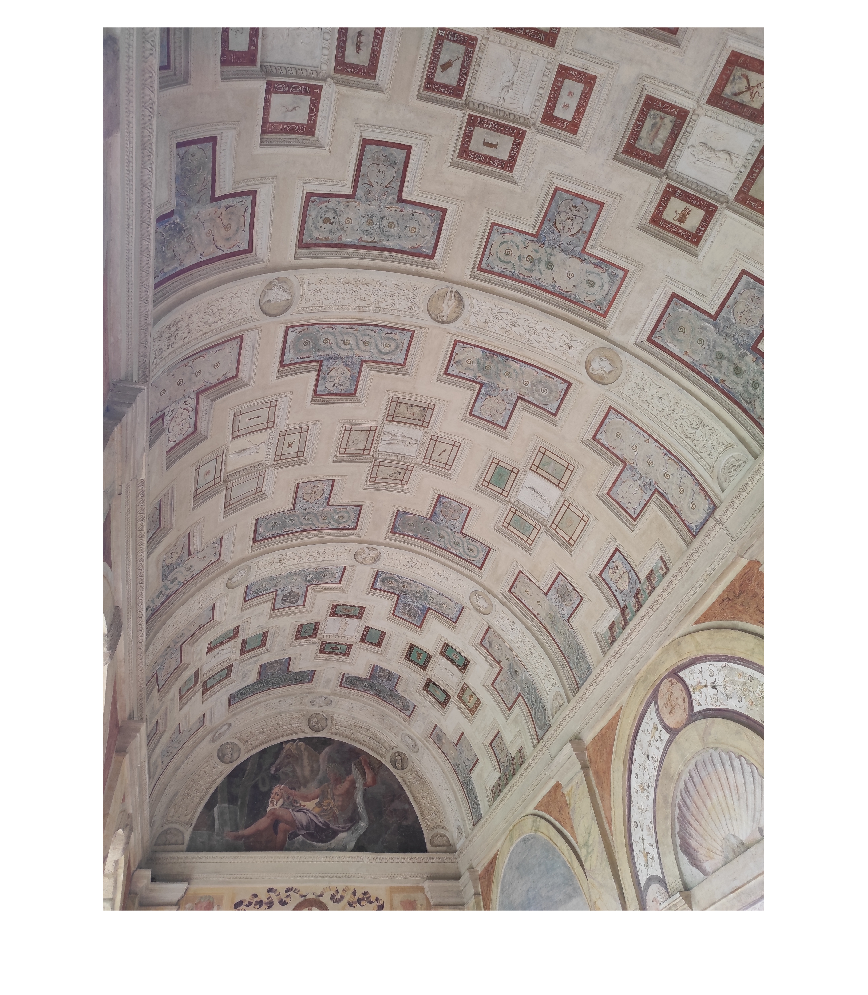

clear all;
im = imread('PalazzoTe.jpg');

%rotate the image
img=imrotate(im, -90);

%show the image

imshow(img);

## **IMPORT NECESSARY GEOMETRIC ELEMENTS**

C1=load('elements\CONICS\C1.mat').C1

C1 =     0.0000   -0.0000   -0.0000
   -0.0000    0.0000   -0.0004
   -0.0000   -0.0004    1.0000


C2=load('elements\CONICS\C2.mat').C2

C2 =     0.0000   -0.0000   -0.0001
   -0.0000    0.0000   -0.0002
   -0.0001   -0.0002    1.0000



l1=load('elements\LINES\line_l1.mat').line_l1

l1 =    -0.0042
   -0.0000
    1.0000


l2=load('elements\LINES\line_l2.mat').line_l2

l2 =    -0.0002
   -0.0001
    1.0000



horizon=load('elements\LINES\horizon.mat').horizon

horizon =    -0.0005
    0.0018
    1.0000


## **COMPUTE THE IMAGES OF THE TWO CENTERS OF THE TWO CIRCUMFERENCES**

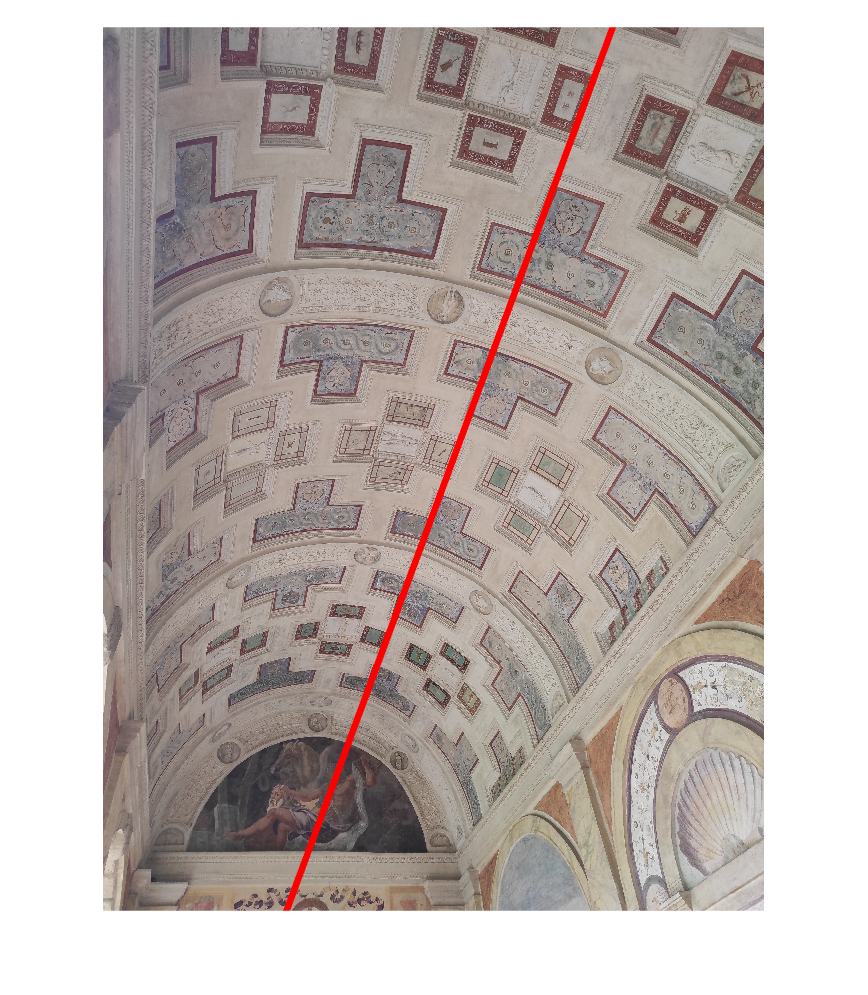

center1=inv(C1)* horizon;
center2=inv(C2)* horizon;
axis=line_through_two_pts(center1,center2,img,true);


save('elements\CONICS\centerC1.mat','center1')
save('elements\CONICS\centerC2.mat','center2')
save('elements\LINES\axis.mat' ,'axis')

## **COMPUTE VANISHING POINT V **

V=intersection_point_3_lines(l1,l2,axis);
figure;
imshow(img)
hold on
plot(V(1) , V(2) ,'ro', 'MarkerSize', 10, 'LineWidth', 2);
hold off;


save('elements\VANISHING POINTS\V.mat' , "V")